file_names = pyrunfile("model_for_testing.py", 'L_file_names')

file_names =   Python list with values:

    ['dataout/nodes0.txt', 'dataout/nodes4.txt']

    Use string, double or cell function to convert to a MATLAB array.


file_names = string(cell(file_names))

file_names = 1×2 string array
    "dataout/nodes0.txt"    "dataout/nodes4.txt"


graph_num = 0

graph_num = 0

nodes = 3600×5 table
    Var1     Var2      Var3    Var4    Var5
    ____    _______    ____    ____    ____

    -50         -10     0       1       1  
    -50     -9.6552     0       1       1  
    -50     -9.3103     0       1       1  
    -50     -8.9655     0       1       1  
    -50     -8.6207     0       1       1  
    -50     -8.2759     0       1       1  
    -50      -7.931     0       1       1  
    -50     -7.5862     0       1       1  
    -50     -7.2414     0       1       1  
    -50     -6.8966     0       1       1  
    -50     -6.5517     0       1       1  
    -50     -6.2069     0       1       1  
    -50     -5.8621     0       1       1  
    -50     -5.5172     0       1       1  
    -50     -5.1724     0       1       1  
    -50     -4.8276     0       1       1  


num_nodes = 3600

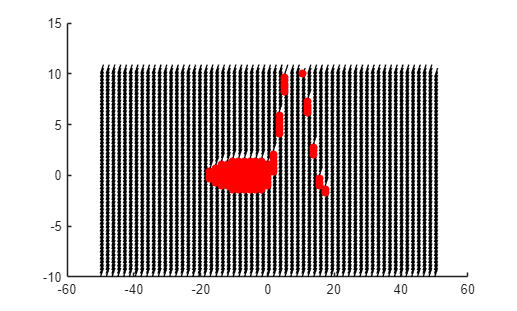

graph_num = 1

nodes = 3600×5 table
    Var1     Var2      Var3    Var4    Var5
    ____    _______    ____    ____    ____

    -50         -10     0       1       1  
    -50     -9.6552     0       1       1  
    -50     -9.3103     0       1       1  
    -50     -8.9655     0       1       1  
    -50     -8.6207     0       1       1  
    -50     -8.2759     0       1       1  
    -50      -7.931     0       1       1  
    -50     -7.5862     0       1       1  
    -50     -7.2414     0       1       1  
    -50     -6.8966     0       1       1  
    -50     -6.5517     0       1       1  
    -50     -6.2069     0       1       1  
    -50     -5.8621     0       1       1  
    -50     -5.5172     0       1       1  
    -50     -5.1724     0       1       1  
    -50     -4.8276     0       1       1  


num_nodes = 3600

graph_num = 2

for i = 1:length(file_names)
    nodes = readtable(file_names(1, i))

    num_nodes = height(nodes)
    
    graph(nodes, num_nodes)

    graph_num = graph_num + 1
end


function graph(nodes, num_nodes)
    figure()
    hold on
    for i = 1:num_nodes-1
        if nodes{i, 3} == 0
            % scatter(nodes{i, 1}, nodes{i, 2}, 'filled', 'black')
            quiver(nodes{i, 1}, nodes{i, 2}, nodes{i, 4}, nodes{i, 5}, 'filled', 'black')
        else
            scatter(nodes{i, 1}, nodes{i, 2}, 'filled', 'red')
            quiver(nodes{i, 1}, nodes{i, 2}, nodes{i, 4}, nodes{i, 5}, 'filled', 'red')
        end
    end
    drawnow;
    exportgraphics(gca, "nodes.gif", 'Append', true);
    hold off
end